# Natural, Damped and Resonant - which is which ?

In structural dynamics we typically have 3 frequencies of interest

- **Undamped natural frequency (**$\omega_n$**)** :    intrinsic property of the structure and depends on MASS and STIFFNESS

- **Damped natural frequency (**$\omega_d$**)** :        frequency of free vibration with damping

- **Resonant frequency (**$\omega_R$**)** :                   frequency of *maximum steady-state response* under harmonic excitation

These frequencies are related via the following parametric equations

- 
$$\omega_d \;\;=\;\omega_n \ldotp \sqrt{1\;-\;\;\;\;\;\;\zeta^2 \;\;}$$


- $\omega_R \;\;=\;\omega_n \ldotp \sqrt{1\;-\;2\ldotp \zeta^2 \;\;}$      *** ..... this is derived below***

When the structure is lightly damped, all three of these frequencies have VERY VERY similar values.  For example:

- When $\zeta =0\ldotp 1$ we still have $\frac{\omega_d }{\omega_n }\approx 0\ldotp 995$ and $\frac{\omega_R }{\omega_n }\approx 0\ldotp 99$

- And typically mechanical structures have damping ratios of the order $\zeta =0\ldotp 001$

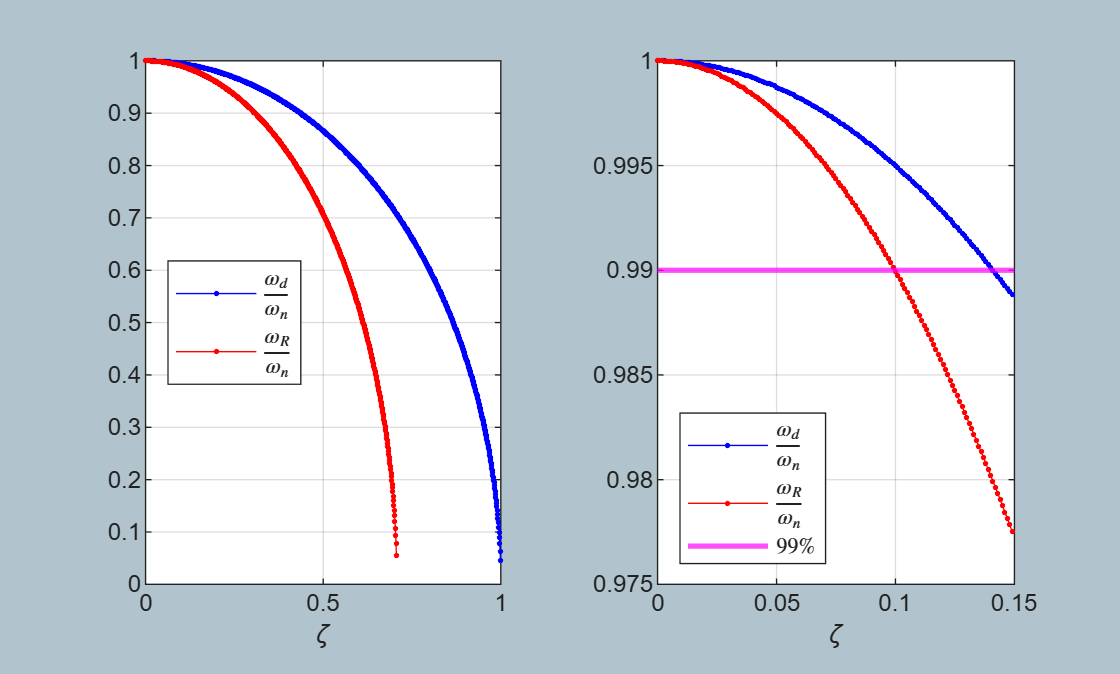

LOC_plot_wd_and_wr_RATIOS()

So let's explore these further using our classic **prototype 2nd‑order system **transfer function:

- 
$$H\left(s\right)\;=\;\frac{\omega_n^2 }{s^2 \;\;\;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;\;+\;\;\;\omega_n^2 }$$


`Bradley Horton:   bhorton@mathWorks.com`

## Symbolic variables and assumptions

Clear all assumptions

clear all  % ALL is needed to clear any existing ASSUMPTIONS

assumptions

 
ans =
 
Empty sym: 1-by-0
 


Define Symbolic variables

syms omega  omega_n  zeta  s

Define assumptions

assume(omega,   "real")
assume(omega_n, "real")
assume(zeta >=0 & zeta <=1)
assumeAlso(zeta, "real")

Echo these assumptions

assumptions

$$ans = \left(\begin{array}{ccccc} \omega \in \mathbb{R} & \omega_{n}\in \mathbb{R} & \zeta \in \mathbb{R} & 0\leq \zeta & \zeta \leq 1 \end{array}\right)$$

## Define the **prototype 2nd‑order system transfer function**

- 
$$H\left(s\right)\;=\;\frac{\omega_n^2 }{s^2 \;\;\;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;\;+\;\;\;\omega_n^2 }$$


H = omega_n^2 / (s^2 + 2*zeta*omega_n*s  + omega_n^2)

$$H = \frac{{\omega_{n}}^{2}}{{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}}$$

Create the Frequency Response Function - $H\left(\omega \right)$

- Substitute  $s=j\ldotp \omega \;$

Hw = subs(H, s, j*omega)

$$Hw = \frac{{\omega_{n}}^{2}}{-\omega^{2}+2\,\mathrm{i}\,\zeta \,\omega \,\omega_{n}+{\omega_{n}}^{2}}$$

## MAGNITUDE - explore

Define the Magnitude of $H\left(\omega \right)$

HwMAG = sqrt( real(Hw)^2 + imag(Hw)^2  )

$$HwMAG = \sqrt{\frac{{\omega_{n}}^{4}\,{\left(\omega^{2}-{\omega_{n}}^{2}\right)}^{2}}{{\left({\left(\omega^{2}-{\omega_{n}}^{2}\right)}^{2}+4\,\omega^{2}\,{\omega_{n}}^{2}\,\zeta^{2}\right)}^{2}}+\frac{4\,\omega^{2}\,{\omega_{n}}^{6}\,\zeta^{2}}{{\left({\left(\omega^{2}-{\omega_{n}}^{2}\right)}^{2}+4\,\omega^{2}\,{\omega_{n}}^{2}\,\zeta^{2}\right)}^{2}}}$$

Look for extremum - i.e.:  when gradient is ZERO

- 
$$\frac{\mathrm{d}}{\mathrm{d}\omega }\left|H\left(\omega \right)\right|\;\;=\;\;0$$


w_at_MAX_MAG = solve( 0==diff(HwMAG, omega), omega, 'ReturnConditions',true)

w_at_MAX_MAG = struct with fields:
         omega: [3×1 sym]
    parameters: [1×0 sym]
    conditions: [3×1 sym]


So at what frequency do we have an EXTREMUM ?

w_at_MAX_MAG.omega

$$ans = \left(\begin{array}{c} 0\\ \omega_{n}\,\sqrt{1-2\,\zeta^{2}}\\ -\omega_{n}\,\sqrt{1-2\,\zeta^{2}} \end{array}\right)$$

And what conditions are required for this ?

w_at_MAX_MAG.conditions

$$ans = \left(\begin{array}{c} \left({\left({\omega_{n}}^{2}\,\left(2\,\zeta^{2}-1\right)+{\omega_{n}}^{2}\right)}^{2}\neq 4\,{\omega_{n}}^{4}\,\zeta^{2}\,\left(2\,\zeta^{2}-1\right)\wedge 0<2\,\zeta^{2}-1\right)\vee \left({\left({\omega_{n}}^{2}\,\left(2\,\zeta^{2}-1\right)+{\omega_{n}}^{2}\right)}^{2}\neq 4\,{\omega_{n}}^{4}\,\zeta^{2}\,\left(2\,\zeta^{2}-1\right)\wedge 2\,\zeta^{2}-1\leq 0\right)\\ {\left({\omega_{n}}^{2}\,\left(2\,\zeta^{2}-1\right)+{\omega_{n}}^{2}\right)}^{2}\neq 4\,{\omega_{n}}^{4}\,\zeta^{2}\,\left(2\,\zeta^{2}-1\right)\wedge 2\,\zeta^{2}-1\leq 0\\ {\left({\omega_{n}}^{2}\,\left(2\,\zeta^{2}-1\right)+{\omega_{n}}^{2}\right)}^{2}\neq 4\,{\omega_{n}}^{4}\,\zeta^{2}\,\left(2\,\zeta^{2}-1\right)\wedge 2\,\zeta^{2}-1\leq 0 \end{array}\right)$$

So the frequency that causes that LARGEST steady state response  , i.e.: the RESONANT frequency is:

w_at_MAX_MAG.omega(2)

$$ans = \omega_{n}\,\sqrt{1-2\,\zeta^{2}}$$

Also, NOTE:

max_allowed_zeta = sqrt(1/2)

max_allowed_zeta = 0.7071

## PHASE - explore

What's the REAL part ?

real(Hw)

$$ans = -\frac{{\omega_{n}}^{2}\,\left(\omega^{2}-{\omega_{n}}^{2}\right)}{{\left(\omega^{2}-{\omega_{n}}^{2}\right)}^{2}+4\,\omega^{2}\,{\omega_{n}}^{2}\,\zeta^{2}}$$

What's the IMAGINARY part ?

imag(Hw)

$$ans = -\frac{2\,\omega \,{\omega_{n}}^{3}\,\zeta }{{\left(\omega^{2}-{\omega_{n}}^{2}\right)}^{2}+4\,\omega^{2}\,{\omega_{n}}^{2}\,\zeta^{2}}$$

So ? - So when $\omega =\omega_n$ then the real part is ZERO ... and the imaginary part is NEGATIVE

- **PHASE** =` -90 degrees` @ $\omega =\omega_n$

# Get ready for a Numeric example

Create some MATLAB Function handles for computing $\left|H\left(\omega \right)\right|$

HwMAG_MLF   = matlabFunction(HwMAG, "Vars", [omega, omega_n, zeta] )

HwMAG_MLF = function_handle with value:
    @(omega,omega_n,zeta)sqrt(omega_n.^4.*(omega.^2-omega_n.^2).^2.*1.0./((omega.^2-omega_n.^2).^2+omega.^2.*omega_n.^2.*zeta.^2.*4.0).^2+omega.^2.*omega_n.^6.*zeta.^2.*1.0./((omega.^2-omega_n.^2).^2+omega.^2.*omega_n.^2.*zeta.^2.*4.0).^2.*4.0)


And the RESONANT frequency that gives MAX $\left|H\left(\omega \right)\right|$

w_at_MAX_MAG_MLF = matlabFunction(w_at_MAX_MAG.omega(2), "Vars", [omega_n, zeta] )

w_at_MAX_MAG_MLF = function_handle with value:
    @(omega_n,zeta)omega_n.*sqrt(zeta.^2.*-2.0+1.0)


# A Numeric example

my_zeta = 0.2;
my_wn   = 10;

Plot - part 1

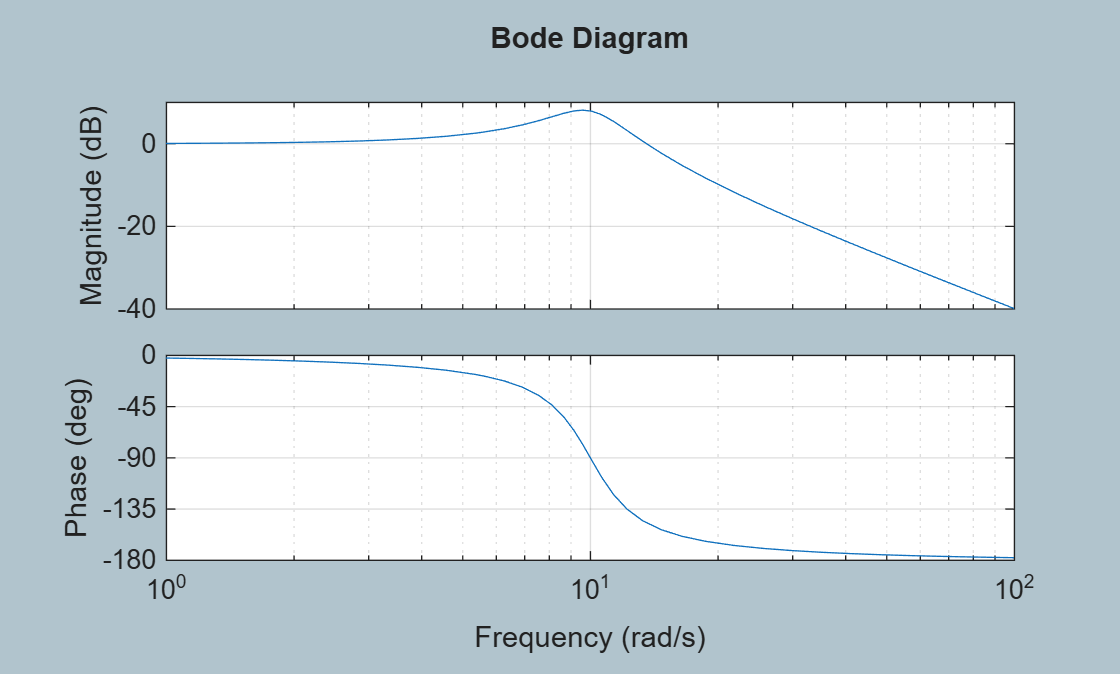

tmp_H = tf(my_wn^2, [1, 2*my_zeta*my_wn, my_wn^2]);

figure;
    bodeplot(tmp_H);
        grid on

Compute DAMPED frequency and RESONANT frequency

my_wd   = my_wn*sqrt(1 - my_zeta^2);
my_wr   = w_at_MAX_MAG_MLF(my_wn, my_zeta);

Echo these things

tmp_col = [my_wr;  my_wd;  my_wn];
tmp_mat = [tmp_col,  tmp_col/my_wn];

array2table(tmp_mat, "RowNames",["w_RESONANCE", "w_damped", "w_n"], "VariableNames",["w", "w/w_n"])

ans = 3×2 table
                     w        w/w_n 
                   ______    _______

    w_RESONANCE    9.5917    0.95917
    w_damped        9.798     0.9798
    w_n                10          1


Pick a frequency range to plot 

min_w_of_interest = min([my_wn, my_wd, my_wr]);
max_w_of_interest = max([my_wn, my_wd, my_wr]);

%w_list      = 0:0.01:100;
%w_list      = linspace(0.7*min_w_of_interest, 1.3*max_w_of_interest, 1000);
w_list      = linspace(0.9*min_w_of_interest, 1.1*max_w_of_interest, 1000);

Compute

HwMAG_MLF_w = @(w) HwMAG_MLF(w, my_wn, my_zeta);
HwMAG_list  = HwMAG_MLF_w(w_list);

Plot - part 2

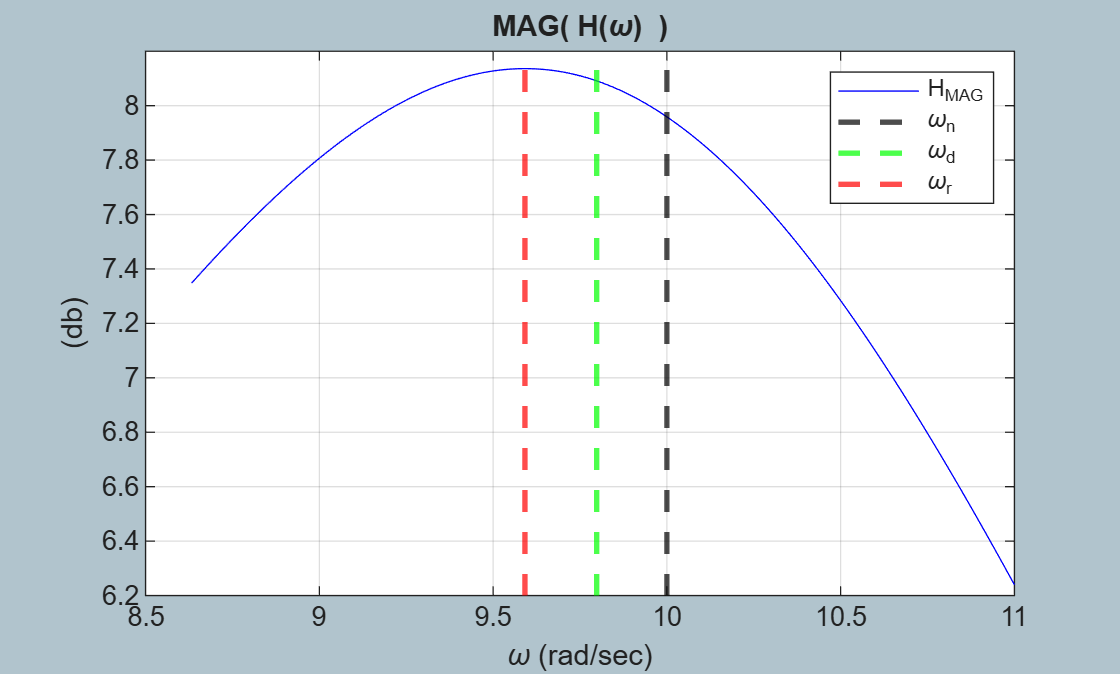

figure;
    plot(w_list, 20*log10(HwMAG_list), "-b", DisplayName="H_{MAG}");
        grid on
        xlabel("\omega (rad/sec)");
        ylabel("(db)")

hold on
    xline(my_wn, "--k", LineWidth=2, DisplayName="\omega_{n}");
    xline(my_wd, "--g", LineWidth=2, DisplayName="\omega_{d}");
    xline(my_wr, "--r", LineWidth=2, DisplayName="\omega_{r}");
        legend("Location","northeast")
        title("MAG( H(\omega)  )")

Plot - part 3

Plot the Bode again

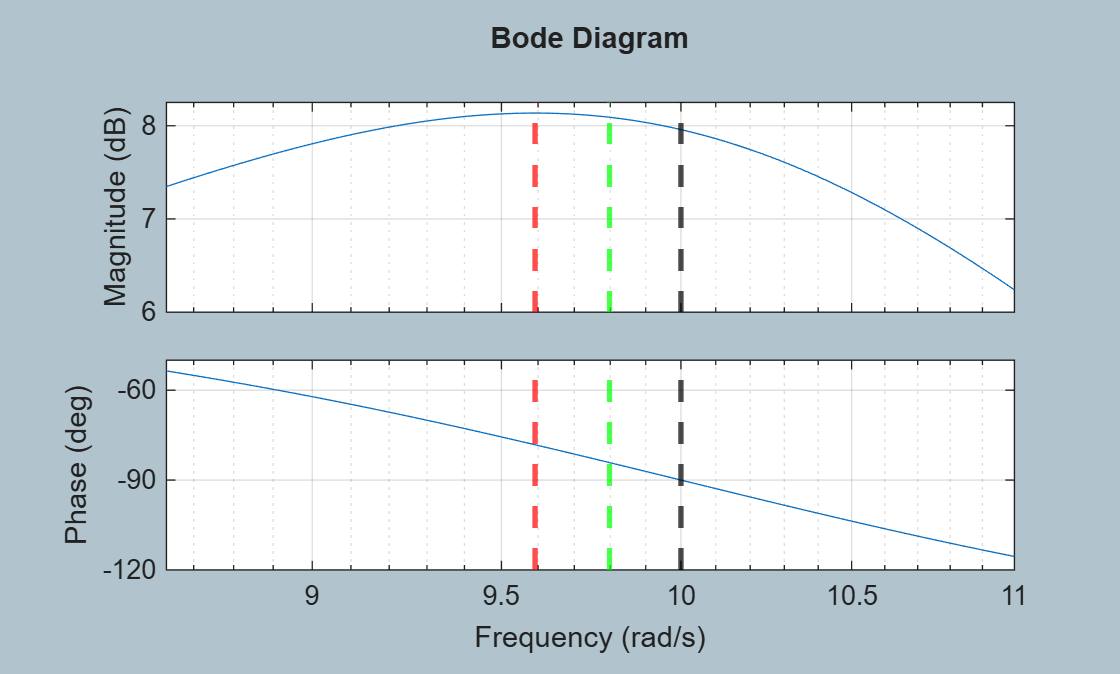

tmp_H = tf(my_wn^2, [1, 2*my_zeta*my_wn, my_wn^2]);

hf = figure;
   bp =  bodeplot(tmp_H, w_list);
        grid on    
drawnow
tmp_ax = findall(hf,'Type','axes');

hold(tmp_ax(1), "on")
axes(tmp_ax(1));
    xline(my_wn, "--k", LineWidth=2, DisplayName="\omega_{n}");
    xline(my_wd, "--g", LineWidth=2, DisplayName="\omega_{d}");
    xline(my_wr, "--r", LineWidth=2, DisplayName="\omega_{r}");

hold(tmp_ax(2), "on")
axes(tmp_ax(2));
    xline(my_wn, "--k", LineWidth=2, DisplayName="\omega_{n}");
    xline(my_wd, "--g", LineWidth=2, DisplayName="\omega_{d}");
    xline(my_wr, "--r", LineWidth=2, DisplayName="\omega_{r}");

# Remove Assumptions on Symbolic variables

What are the current assumptions ?

assumptions       

$$ans = \left(\begin{array}{ccccc} \omega \in \mathbb{R} & \omega_{n}\in \mathbb{R} & \zeta \in \mathbb{R} & 0\leq \zeta & \zeta \leq 1 \end{array}\right)$$

Now remove the assumptions

assume([omega  omega_n  zeta], "clear")    

And confirm

assumptions      

 
ans =
 
Empty sym: 1-by-0
 


# **Local Subfunctions only past this point**

**Let's plot the following**

- $\frac{\omega_d }{\omega_n \ldotp }\;\;=\;\sqrt{1\;-\;\;\;\;\;\;\zeta^2 \;\;}$     and     $\frac{\omega_R }{\omega_n \ldotp }\;\;=\;\sqrt{1\;-\;2\ldotp \zeta^2 \;\;}$

function LOC_plot_wd_and_wr_RATIOS()

    zeta_list_D = 0:0.001:0.999;
    zeta_list_R = 0:0.001:0.706;

    wd_div_wn = sqrt( 1 -   zeta_list_D.^2 );
    wR_div_wn = sqrt( 1 - 2*zeta_list_R.^2 );    

    figure;

    tiledlayout(1,2)

    nexttile
        plot(zeta_list_D, wd_div_wn, "-b.",  DisplayName="$\frac{\omega_d}{\omega_n}$");
            xlabel("\zeta");   grid on
        hold on
            plot(zeta_list_R, wR_div_wn, "-r.", DisplayName="$\frac{\omega_R}{\omega_n}$");
            legend("Location","best", Interpreter="latex")          
    nexttile
        inds_D = zeta_list_D < 0.15;
        inds_R = zeta_list_R < 0.15;

            plot(zeta_list_D(inds_D), wd_div_wn(inds_D), "-b.", DisplayName="$\frac{\omega_d}{\omega_n}$");
                xlabel("\zeta");   grid on
        hold on
            plot(zeta_list_R(inds_R), wR_div_wn(inds_R), "-r.", DisplayName="$\frac{\omega_R}{\omega_n}$");
                xlabel("\zeta");   grid on     
            yline(0.99, "-m", LineWidth=2, DisplayName="$99\%$")    
            legend("Location","southwest", Interpreter="latex")    
end